# GNSS

## parameters

% latitude - phi
LaD = 59;  % 47
LaM = 20;  % 0
LaS = 59;  % 0
% longitude - lambda
LoD = 18;  % 15
LoM = 4;  % 0
LoS = 10;  % 0

lat = LaD + LaM / 60 + LaS / 3600

lat = 59.3497

lon = LoD + LoM / 60 + LoS / 3600

lon = 18.0694

h = 62 + 23;
[X,Y,Z]=Car2Ellip(lat, lon, h);
[Xt,Yt,Zt]=Car2Ellip(lat, lon, h+100);
data=readmatrix('GPS_position.xlsx');
id=data(:,1);
Xs=data(:,2);
Ys=data(:,3);
Zs=data(:,4);
[lat, lon, h] = Ellop2Car(X, Y, Z);

Xi=[X;Y;Z];
Xij=[Xs*1000-X,Ys*1000-Y,Zs*1000-Z];

%a=[Xt-X,Yt-Y,Zt-Z]
%xt=R'*a'
%st=(sqrt(power(xt(1), 2) + power(xt(2), 2) + power(xt(3), 2)))  % spatial distance
%at=(rad2deg(atan2(xt(2), xt(1))))  % azimuth
%zt=(rad2deg(acos(xt(3) / (sqrt(power(xt(1), 2) + power(xt(2), 2) + power(xt(3), 2))))))

%define rotation matrix
R=[-sind(lat)*cosd(lon), -sind(lon), cosd(lat)*cosd(lon);-sind(lat)*sind(lon),cosd(lon),cosd(lat)*sind(lon);cosd(lat),0,sind(lat)]

R =    -0.8179   -0.3102    0.4847
   -0.2668    0.9507    0.1581
    0.5098         0    0.8603


sij=zeros(1,29);
alpha_ij=zeros(1,29);
zij=zeros(1,29);
for i=1:29
    xij=R'*(Xij(i,:)');
    sij(i)=(sqrt(power(xij(1), 2) + power(xij(2), 2) + power(xij(3), 2)));  % spatial distance
    alpha_ij(i)=(rad2deg(atan2(xij(2), xij(1))));  % azimuth
    zij(i)=(rad2deg(acos(xij(3) / (sqrt(power(xij(1), 2) + power(xij(2), 2) + power(xij(3), 2))))));
end
el=90*ones(1,29)-zij;
cnt=0;
ID=zeros(1,29);
az=zeros(1,29);
index=zeros(1,29);
for i=1:29
    if((el(i)<=90) && (el(i)>=0))
        cnt=cnt+1;
        ID(i)=id(i);
        index(i)=i;
        
    end
end
cnt

cnt = 11

## crazy staff

index=nonzeros(index)';
PRN=nonzeros(ID')';
alpha_ij

alpha_ij =   152.5788  -60.0622  172.8502  -70.0698   46.7453  107.9559  -32.6283  -75.1947   25.4253   19.2372  -90.8762 -136.9971  111.4999  104.9409  174.5041   59.2040 -172.1772 -125.1429  103.0119   66.6558 -157.0347  -75.7555  136.6581    0.6258  -98.6855  -60.9330   -4.0154   73.1865  -45.2435


for i=1:cnt
    if(alpha_ij(index(i))<0)
        az(index(i))=360+alpha_ij(index(i));
    else
        az(index(i))=alpha_ij(index(i));
    end
end
az=nonzeros(az')';
for i=1:29
    if(el(i)<0)
        el(i)='n';
    elseif(el(i)>90)
        el(i)='n';
    else
        el(i)=el(i);
    end
end
el=el(el~='n');
%skyplot!
az

az =   152.5788  172.8502  327.3717   25.4253  269.1238  111.4999  187.8228  234.8571   66.6558  299.0670  314.7565


el

el =    31.0462   13.2738    1.0948   13.8374   57.4307   47.5224   42.8707   11.0527   32.0288   22.5088   20.2997


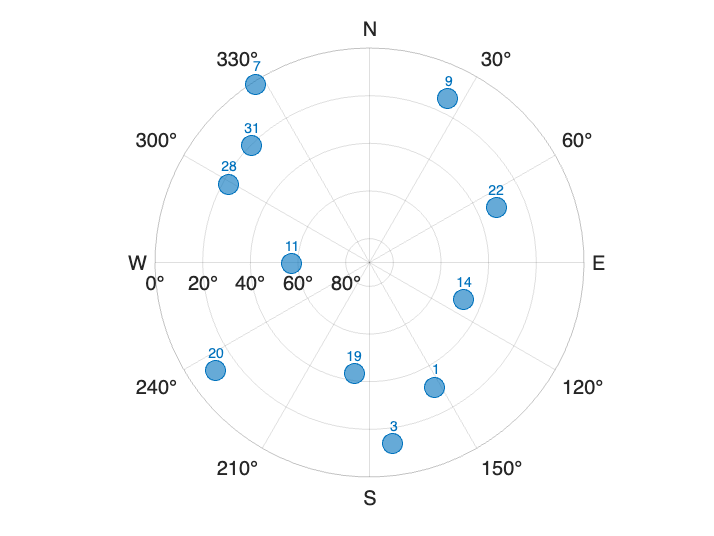

skyplot(az,el,PRN)

## Function

function [X,Y,Z]=Car2Ellip(lat, lon, h)
    a = 6378137;  % semi major axis
    fe = 1 / 298.257222101;
    b = a - fe * a;  % semi minor axis
    N = power(a, 2) / sqrt(power(a, 2) * power(cosd(lat), 2) + power(b, 2) * power(sind(lat), 2));
    X = (N + h) * cosd((lat)) * cosd(lon);
    Y = (N + h) * cosd(lat) * sind(lon);
    Z = (power(b / a, 2) * N + h) * sind(lat);
    % print(X,Y,Z)
end

function [lat0, lon, h]=Ellop2Car(X, Y, Z)
    a = 6378137;  % semi major axis
    fe = 1 / 298.257222101;
    b = a - fe * a; % semi minor axis
    e2 = (power(a, 2) - power(b, 2)) / power(a, 2);
    p = sqrt(power(X, 2) + power(Y, 2));
    lat0 = rad2deg(atan2((Z / p) * (power((1 - e2), -1)),1));
    lat = 0;
    while (lat~=lat0)
        N0 = power(a, 2) / sqrt(power(a, 2) * power(cosd(lat0), 2) + power(b, 2) * power(sind(lat0), 2));
        h = p / cosd(lat0) - N0;
        lat = rad2deg(atan2((Z / p) * power(1 - e2 * (N0 / (N0 + h)), -1),1));
        lat0 = lat;
        lon = rad2deg(atan2(Y,X));
        h = p / cosd(lat0) - N0;
    end

end
